Preparation

clear

tic

Paramater Settings

startdate = '30-Dec-2010' 

startdate = '30-Dec-2010'

startdate = datetime (startdate ,'InputFormat',"dd-MMM-uuuu") ;
enddate = '30-Dec-2016' ;
enddate  = datetime (enddate ,'InputFormat',"dd-MMM-uuuu") ;


MinValue = 1*10^9 

MinValue = 1.0000e+09

ValueSurgeThresholdX = 1;
MomContDays = 10 ;
MomContRetTrheshold = 2/100 ; 
LowLiquidDays = 20 ;
LowLiquidThreshold = 1*10^6 ;
LiquidSurgThreshold = 3 ;
LiquidSurgAvgLeadDays = 5 ;
LiquidSurgAvgLagDays = 200 ;
MomMainDays = 30 ;
MomMainRetThreshold = 30/100 ; 
PostSignalBufferDays = 2 ;
StopLossLookbackWindSz = 15;
StopLossThreshold = 8/100 ;
MinNSymDivers = 8 ;
MinNSymLever = 12 ;
DERLevel = 0.1/100 ;
TradingCosts = [0.2/100 0.3/100] ;


Read data  

PriceTT =  readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");
VolumeTT = readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Volume Data");
IndexTT = readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Index Data");

Data cleaning

PriceTT = fillmissing (PriceTT, "previous");
VolumeTT = fillmissing (VolumeTT, "previous");
IndexTT = fillmissing (IndexTT, "previous");

Sort Symbols Alphabetically 

SymList =  PriceTT.Properties.VariableNames;
SymList = sort (SymList);
uniq = unique (SymList);
SymList (:,end);

PriceTT = PriceTT (:, SymList);
VolumeTT = VolumeTT (:,SymList);

clear uniq

Transaction Value

PriceTT ;
ValueTT = PriceTT ;
ValueTT.Variables = PriceTT.Variables .* VolumeTT.Variables ;

clear VolumeTT

Liquidity constraints

LiquiditySignal = PriceTT ;
ValueVar = ValueTT.Variables ; 
Signal = ValueVar > MinValue ;
Signal (isnan(Signal)) = 0;
LiquiditySignal.Variables = Signal ;
LiquiditySignal ;

clear ValueVar Signal 

Momentum continuation constraints

MomContDays ;
MomContRetTrheshold ;
MomContSignal = PriceTT ;
Price = PriceTT.Variables ;

MomContRet = Price ;
MomContRet (MomContDays:end, :) = Price (MomContDays:end, :) ./ Price (1:end-MomContDays+1, :) - 1 ;
MomContRet (1:MomContDays -1, :) = 0 ;

MomContSignalVar = MomContRet > MomContRetTrheshold ;
MomContSignalVar (isnan (MomContSignalVar)) = 0;
MomContSignal.Variables = MomContSignalVar;

MomContSignal ;
% Troubleshoot & Check
% max(MomContSignal.Variables)
% max(max(MomContSignal.Variables))
% plot(MomContSignal.Time, MomContSignal.BBCA);

clear MomContSignalVar Price MomContRet 

Avoid inconsistent volume in LowLiquidDays period

LowLiquidSignal = ValueTT ;
LowLiquidSignal.Variables = movmin (ValueTT.Variables, [LowLiquidDays 0]) ;
LowLiquidSignalVar = LowLiquidSignal.Variables ;

LowLiquidSignal.Variables = LowLiquidSignalVar >LowLiquidThreshold ;

% ValueTT
LowLiquidSignal;

%LowLiquidSignalVar < low

% plot (LowLiquidSignal.Time, LowLiquidSignal.ACES)
clear LowLiquidSignalVar 

Liquidity surge detector

LiquidSurgeSignal = ValueTT ;
LiquidSurgeSignalVar = LiquidSurgeSignal.Variables ;
LiquidSurgeSignalAvgLead = movmean (LiquidSurgeSignalVar, LiquidSurgAvgLeadDays,1) ;
LiquidSurgeSignalAvgLag = movmean (LiquidSurgeSignalVar, LiquidSurgAvgLagDays,1) ;
LiquidSurgeSignalX = LiquidSurgeSignalAvgLead ./LiquidSurgeSignalAvgLag ;
LiquidSurgeSignalVar = LiquidSurgeSignalX >LiquidSurgThreshold ;
LiquidSurgeSignalVar (1:LiquidSurgAvgLagDays-1, :) = 0 ;

% SymList (9) ;
LiquidSurgeSignal.Variables = LiquidSurgeSignalVar ;

clear LiquidSurgeSignalVar LiquidSurgeSignalAvgLead LiquidSurgeSignalAvgLag LiquidSurgeSignalX LiquidSurgeSignalVar 

Main momentum detector

MomSignal = PriceTT ;
Price = PriceTT.Variables ;
MomSignalVar = MomSignal.Variables ;
Price (MomMainDays:end, :) ;
Price (1:end-MomMainDays+1,:) ;
MomSignalRet = Price (MomMainDays:end, :) ./ Price (1:end-MomMainDays+1,:) -1  ;
MomSignalVar (1:MomMainDays-1, :) = 0;
MomSignalVar (MomMainDays:end, :) = MomSignalRet > MomMainRetThreshold ;
 
MomSignal.Variables = MomSignalVar ;

clear MomSignalVar Price MomSignalRet 

Momentum value combined signal

MomValueCombinedSignal = PriceTT ;
MomValueCombinedSignalVar = LiquidSurgeSignal.Variables  .* MomSignal.Variables .* MomContSignal.Variables ;
MomValueCombinedSignal.Variables  = MomValueCombinedSignalVar ;
MomValueCombinedSignal ;

clear MomValueCombinedSignalVar 

Post signal buffer (Zigsaw stabilizer)

PostSignalBufferDays ;
PostSignBuffer = PriceTT ;
PostSignalBufferVar = movmax (MomValueCombinedSignal.Variables, [PostSignalBufferDays 0], 1) ;

PostSignBuffer.Variables = PostSignalBufferVar ;
PostSignBuffer ;

% plot (PostSignalBuffer.Time, PostSignBuffer.ANTM)

clear PostSignalBufferVar 

Stop-Loss signal

StopLossLookbackWindSz;
StopLossSignal = PriceTT ;
Price = PriceTT.Variables ;
StopLossRetMaxPrice = Price ./ movmax (Price, [StopLossLookbackWindSz, 0], 1) -1   ;
StopLossSignalVar = StopLossRetMaxPrice > - StopLossThreshold ;
StopLossSignal.Variables = StopLossSignalVar ;

% plot (StopLossSignal.Time, StopLossSignal.ARTO)
% a = PriceTT;
% a.Variables = movmax (Price, [StopLossLookbackWindSz, 0], 1);
% plot (a.Time, a.ARTO)

clear StopLossSignalVar StopLossRetMaxPrice Price

Final combined signal

CombSignal = PriceTT ;
CombSignalVar = LiquiditySignal.Variables .* LowLiquidSignal.Variables ...
     .* PostSignBuffer.Variables .* StopLossSignal.Variables ;

CombSignal.Variables = CombSignalVar ;

FinalCombSignal = PriceTT;
FinalCombSignalVar = FinalCombSignal.Variables ;
FinalCombSignalVar  (2:end, :) = CombSignalVar (1:end-1, :);
FinalCombSignalVar (1, :) = 0 ;
FinalCombSignal.Variables = FinalCombSignalVar ;
% plot (FinalCombSignal.Time, FinalCombSignal.BBRI)

clear CombSignalVar FinalCombSignalVar

Capital allocation & Leverage

MinNSymDivers;
MinNSymLever ;
DERLevel ;

NSignalDaily = sum (FinalCombSignal.Variables , 2);
CapAllocDaily  = 1 ./ NSignalDaily ;

CapAllocDaily(isinf (CapAllocDaily)) = 0 ;

% Without leverage range >= MinNSymDivers
CapAllocDaily(CapAllocDaily >= 1/ MinNSymDivers) = 1/ MinNSymDivers ;

% With leverage range >= MinNSymLever
CapAllocDaily(and((CapAllocDaily >= 1/ MinNSymLever),(CapAllocDaily <= 1/ MinNSymDivers))) = (DERLevel+1)/ MinNSymLever  ;

CapAllocPerSym = FinalCombSignal.Variables .* CapAllocDaily ;

TotalCapInvesteDaily = sum (CapAllocPerSym, 2);
NSymDaily = 1 ./ CapAllocDaily;
NSymDaily (isinf(NSymDaily)) = 0 ;

% Check

% max (NSymDaily )
% min (NSymDaily )
% max (TotalCapInvesteDaily)
% min (TotalCapInvesteDaily)
% max (max(CapAllocPerSym))
% min (min (CapAllocPerSym))
% min (CapAllocDaily)
% max (CapAllocDaily)
% min (NSignalDaily)
% max (NSignalDaily)
% plot (CapAllocDaily)
% plot (TotalAlloc)
% plot (NSymDaily)
% plot (NSignalDaily)

clear TotalAlloc NSymDaily CapAllocDaily FinalCombSignalVar 

Pre-Trading Costs return

PriceRetTT = PriceTT ;
Price = PriceTT.Variables ;
PriceRetDaily = Price ;
PriceRetDaily (1, :) = 0 ;
PriceRetDaily (2:end, :) = Price (2:end, :) ./ Price (1:end-1, :) -1 ;
PriceRetDaily (isnan(PriceRetDaily)) = 0 ;
PriceRet = PriceRetDaily .* CapAllocPerSym ;
PriceRetTT.Variables = PriceRet ;


min(min(PriceRet))

ans = -0.0528

max(max(PriceRet))

ans = 0.0292


PriceRetCum = tick2ret (PriceRetTT) ;

% plot (PriceRetCum.Time, PriceRetCum.ARTO) ;
clear PriceRetDaily PriceRet Price 

Trading costs

CapAllocPerSym ;
TradingCosts ;
BuySellSignal = FinalCombSignal ;
BuySellSignalVar = BuySellSignal.Variables ;
BuySellSignalVarLead = BuySellSignalVar ;
BuySellSignalVarLag = BuySellSignalVar ;
BuySellSignalVarLag (2:end, :) = BuySellSignalVar (1:end-1, :) ;

BuySellSignalVar = (BuySellSignalVarLead  - BuySellSignalVarLag) ;
BuySellSignalVar (1, :) = 0 ;

BuySellSignalVar (BuySellSignalVar>0) ;
BuySellSignalVar (BuySellSignalVar<0) ;
BuySellSignalVar (BuySellSignalVar < 0) = (TradingCosts (1)) ;
BuySellSignalVar (BuySellSignalVar > 0) = (TradingCosts (2)) ;
BuySellSignal.Variables = BuySellSignalVar .* CapAllocPerSym ;


% check

% max (max(BuySellSignalVar ))
% min (min(BuySellSignalVar ))

clear BuySellSignalVarLead BuySellSignalVarLag 

    Daily return

FinalPriceRetPerSym = PriceRetTT ;
FinalPriceRetPerSymVar = PriceRetTT.Variables - BuySellSignal.Variables  ;
FinalPriceRetPerSym.Variables = FinalPriceRetPerSymVar ;
FinalPriceRetPerSym ;

% Check
% max (max(PriceRetTT.Variables))
% min(min(PriceRetTT.Variables))
% max(max(BuySellSignal.Variables  ))
% min(min(BuySellSignal.Variables  ))
% max (max (FinalPriceRetPerSym.Variables ))
% min (min(FinalPriceRetPerSym.Variables ))
% FinalPriceRetPerSymVar (FinalPriceRetPerSymVar > 0)
% FinalPriceRetPerSymVar (FinalPriceRetPerSymVar < 0)

clear FinalPriceRetPerSymVar 

Portfolio Level Return

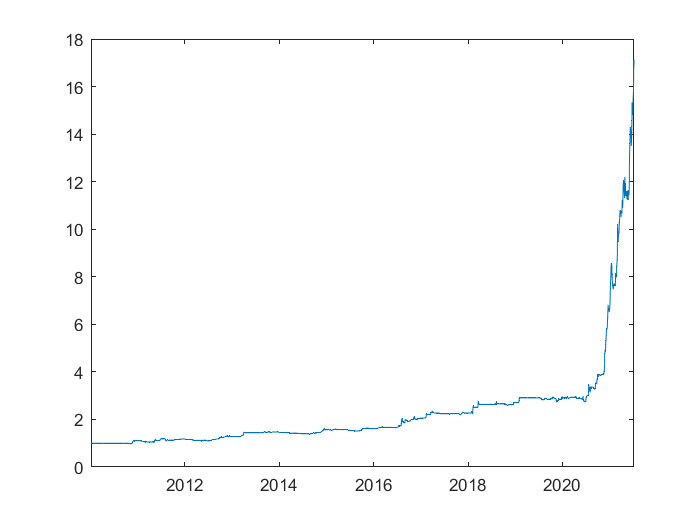

DailyRetPort = timetable(FinalPriceRetPerSym.Time, FinalPriceRetPerSym.BBCA, 'VariableNames', "DailyReturnPort") ;
DailyRetPort.Variables = sum (FinalPriceRetPerSym.Variables,2 ) ;

CumSumPort = ret2tick (DailyRetPort);

plot (CumSumPort.Time, CumSumPort.DailyReturnPort)

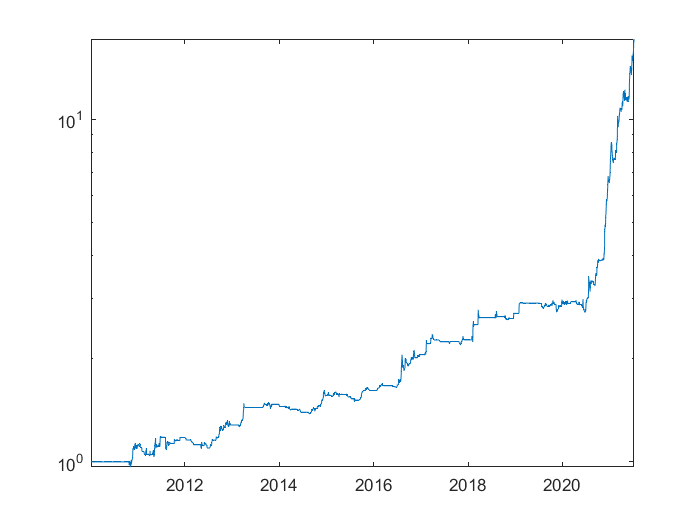

semilogy (CumSumPort.Time, CumSumPort.DailyReturnPort)

Performance analysis

MAR = 0 ;

MaxDailyRet = max (DailyRetPort.Variables)

MaxDailyRet = 0.1212

MinDailyRet = min (DailyRetPort.Variables)

MinDailyRet = -0.0596

a = CumSumPort.DailyReturnPort;
EndCumSum = a(end)

EndCumSum = 17.1429

MaxCumSum = max (CumSumPort.DailyReturnPort)

MaxCumSum = 17.1429

MinCumSum = min (CumSumPort.DailyReturnPort)

MinCumSum = 0.9663


b = CumSumPort.Time ;
c = a == min (CumSumPort.DailyReturnPort) ;
DateMinCumSum = b (a == c) ;
TradingPeriod = yearfrac (b(1), b(end))

TradingPeriod = 11.5178

CAGR = a(end) ^ (1/(TradingPeriod )) -1 

CAGR = 0.2798

SharpeRatio = sharpe(DailyRetPort.Variables, 0) * sqrt (250)

SharpeRatio = 1.7323

Sortino = (mean(DailyRetPort.Variables) - MAR) / sqrt(lpm(DailyRetPort.Variables, MAR, 2)) * sqrt (250)

Sortino = 3.5094

[MaxDD,MaxDDIndex] =  maxdrawdown (CumSumPort.DailyReturnPort);
MaxDD

MaxDD = 0.1275

StartEndMaxDD = b(MaxDDIndex)

StartEndMaxDD = 2×1 datetime array
   15-Jan-2021
   29-Jan-2021



% plot(PriceTT.Time, PriceTT.ARTO)
% plot(PriceTT.Time, PriceTT.DCII)
% plot(PriceTT.Time, PriceTT.DCII)

clear a b c

Latest Signal from Last Trading Day

LatestSignal = FinalCombSignal (end,:)

LatestSignal = 1×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    

a = LatestSignal.Variables ;
b = LatestSignal.Properties.VariableNames ;
SymSignal = b(a>0);
SymSignal = cell2table (transpose(SymSignal) ) ;
SymSignal.Properties.VariableNames = "Symbols Signal";

SymSignal

SymSignal = 12×1 table
    Symbols Signal
    ______________

       {'ADMG'}   
       {'AGII'}   
       {'AMRT'}   
       {'BNLI'}   
       {'MMLP'}   
       {'MRAT'}   
       {'NOBU'}   
       {'PCAR'}   
       {'PRDA'}   
       {'PRIM'}   
       {'SCMA'}   
       {'SRTG'}   


clear a b

Write Signal to Output File

% writetable (SymSignal, "Trend Trading Input Output Data.xlsx", 'sheet', "Output Data")

Check section

% max (max(LiquiditySignal.Variables)) 
% max (max(LowLiquidSignal.Variables)) 
% max (max(StopLossSignal.Variables))
% max (max(LiquidSurgeSignal.Variables))
% max (max(MomSignal.Variables))
% max (max(PostSignBuffer.Variables))
% max (max(MomValueCombinedSignal.Variables))
% max (max(MomContSignal.Variables))


b = CumSumPort.Time 

b = 2859×1 datetime array
   04-Jan-2010
   05-Jan-2010
   06-Jan-2010
   07-Jan-2010
   08-Jan-2010
   11-Jan-2010
   12-Jan-2010
   13-Jan-2010
   14-Jan-2010
   15-Jan-2010
   18-Jan-2010
   19-Jan-2010
   20-Jan-2010
   21-Jan-2010
   22-Jan-2010
   25-Jan-2010
   26-Jan-2010
   27-Jan-2010
   28-Jan-2010
   29-Jan-2010
   01-Feb-2010
   02-Feb-2010
   03-Feb-2010
   04-Feb-2010
   05-Feb-2010
   08-Feb-2010
   09-Feb-2010
   10-Feb-2010
   11-Feb-2010
   12-Feb-2010



stardateIndex = b(b == datetime (startdate))

stardateIndex = datetime
   30-Dec-2010


enddateIndex = b(b == datetime (enddate))  

enddateIndex = datetime
   30-Dec-2016


b(end)

ans = datetime
   09-Jul-2021


find (b==startdate)

ans = 245

find (b==enddate)

ans = 1717


clear b

toc

Elapsed time is 47.776924 seconds.
